# 最小拍控制系统

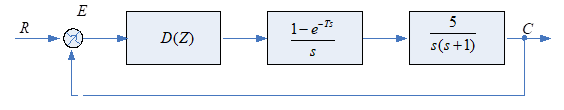

`采样周期为`**T=0.1s**

T=0.1;
G=zpk([],[0 -1],5)

G =
 
     5
  -------
  s (s+1)
 
Continuous-time zero/pole/gain model.



## `一、最小拍有纹波系统`

`针对图一所示的计算机控制系统,考虑输入为单位速度信号时，进行``计算机控制算法``D(Z)设计，编程实现最小拍有纹波系统；`

### 1.1根据广义脉冲传递函数求解闭环传递函数

`通过对连续传递函数进行离散化，获得对象的离散传递函数：`

Gd=c2d(G,T,'zoh');
%Wd的零极点
[zero,pole,~]=zpkdata(Gd);
zero=zero{1};pole=pole{1};
Gd.Variable='z^-1';
display(Gd);

Gd =
 
  0.024187 z^-1 (1+0.9672z^-1)
  ----------------------------
    (1-z^-1) (1-0.9048z^-1)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



从结果可以看出，广义脉冲传递函数含有单位圆上的极点$p_1=1$，有滞后环节$z^{-1}$。但是在单位圆上和单位圆外除(1,0)点无零极点，无纯滞后环节。可以直接应用简单对象的设计方法

由于输入为单位速度信号$r(t)=t$,z变换后为$R(z)=\frac{Tz^{-1}}{(1-z^{-1})^2$，$m=2$查表5.1[2]得

q=2;
z=tf('z',T);  %z用于系统建模
z1=sym('z1'); %z^(-1)用于系数的计算
syms a b c
F1=a+b*z1;
F2=c;
WB=z1*F1;
We=(1-z1)^q*F2;
poly=WB+We-1;
coef=coeffs(poly,z1);
r=solve(coef==0);
a=double(r.a);b=double(r.b);c=double(r.c);
WB=z^(-1)*(a+b*z^(-1));

### 1.2求解数字控制器的脉冲传递函数

%代数方法反推出控制器传递函数，这里会有误差
D=WB/(Gd*(1-WB));
D=minreal(D)

D =
 
                               
  82.689 (1-0.5z^-1)           
                               
                 (1-0.9048z^-1)
                               
  -----------------------------
                            
     (1+0.9672z^-1) (1-z^-1)
                            
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



### 1.3分析数字控制器D(z)对系统的控制效果

当控制信号为单位速度信号时，可以看出经过两拍（两个采样周期），即调整时间为两个采样周期，第三个周期后偏差恒等于零。

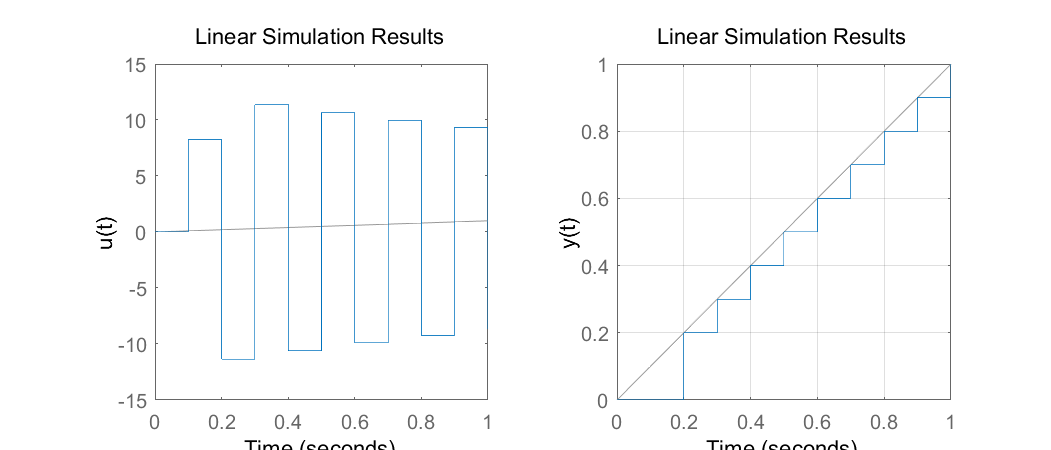

figure('position',[0,0,700,300]);
subplot(1,2,1)
lsimplot(WB/Gd,0:0.1:1,0:0.1:1);
ylabel('u(t)');
subplot(1,2,2);
lsimplot(WB,0:0.1:1,0:0.1:1);
grid on;
ylabel('y(t)');

## `二、最小拍无纹波系统`

讨论纹波的生成原因，编程实现最小拍无纹波系统；

### 2.0 纹波产生的原因

如果系统进入稳态后，加在被控对象上的控制信号还在波动，则稳态过程中系统输出就有纹波。

### 2.1 计算闭环传递函数

在有纹波最小拍系统的基础上，还需要满足闭环传递函数包含对象传递函数所有零点的条件

beta=zero(1);%WB需要包含所有零点
p=pole(1);%We需要包含单位圆上和单位元外极点
%待定系数法求取闭环函数
syms z1 a b c d
F1=a+b*z1;
F2=c+d*z1;
We2=F1*(1-z1)^q;
WB2=F2*z1*(1-beta*z1);
f=We2+WB2-1;
cond=coeffs(f,z1);
r=solve(cond==0);
p_add=double(r.c);
d=double(r.d);
WB2=(p_add+d*z^(-1))*z^(-1)*(1-beta*z^(-1));
We2=1-WB2;

### 2.2数字控制器D的计算

D2=1/Gd*WB2/(1-WB2);
D2=minreal(D2)

D2 =
 
                               
  52.367 (1-0.9048z^-1)        
                               
                 (1-0.5987z^-1)
                               
  -----------------------------
                            
     (1+0.7334z^-1) (1-z^-1)
                            
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



### 2.3分析数字控制器D(z)对系统的控制效果

    通过仿真模拟，绘制相关输出响应曲线，发现系统需要四拍才能进入稳定。

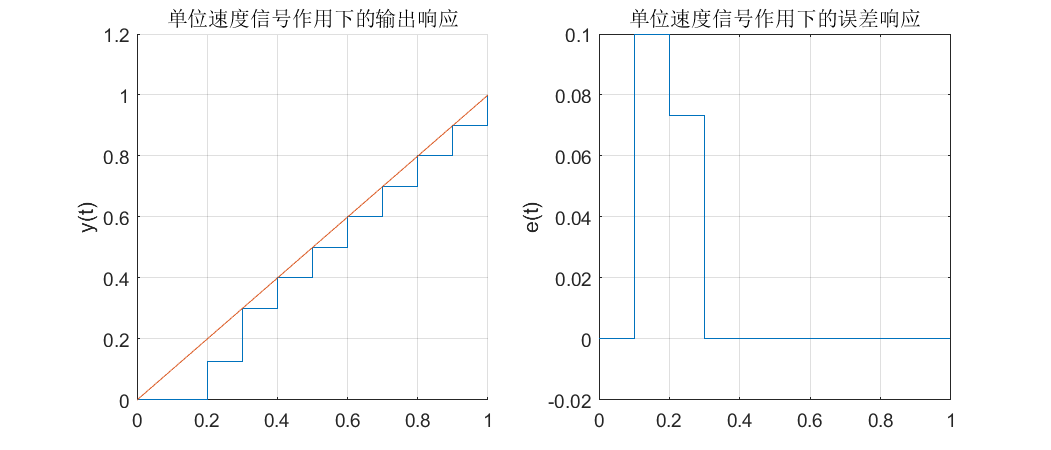

t2=0:0.1:1;
r2=t2;
y2=lsim(WB2,r2,t2);
figure('position',[0,0,700,300]);
subplot(1,2,1);hold on;
stairs(t2,y2);
plot(t2,r2);
hold off;
title("单位速度信号作用下的输出响应")
ylabel('y(t)');grid on;
subplot(1,2,2)
stairs(t2,r2'-y2);
title("单位速度信号作用下的误差响应")
ylabel('e(t)');grid on;

## `三、改进最小拍系统`

`讨论最小拍系统的特点，采取惯性因子法对最小拍控制器加以改进，并研究惯性因子对系统性能的影响。`

%阻尼因子
C=0:0.2:1;
N=length(C);
WB3=repmat(z,[1,N]);
for i=1:N
    p_add=C(i);
    beta=zero(1);%WB需要包含所有零点
    %待定系数法求取闭环函数
    syms a b c d e
    F1=a+b*z1;
    F2=c+d*z1+e*z1^2;
    We=F1*(1-p_add*z1)*(1-z1)^q;
    WB=F2*z1*(1-beta*z1);
    f=We+WB-1;
    cond=coeffs(f,z1);
    r=solve(cond==0);
    c=double(r.c);
    d=double(r.d);
    e=double(r.e);
    WB3(i)=(c+d*z^(-1)+e*z^(-2))*z^(-1)*(1-beta*z^(-1));
end

labels = cell(N+1,1);
labels{1}="r(t)";
for i4 = 1:N
    labels{i4+1} = sprintf('p=%g',C(i4));
end

当输入信号为单位速度信号时

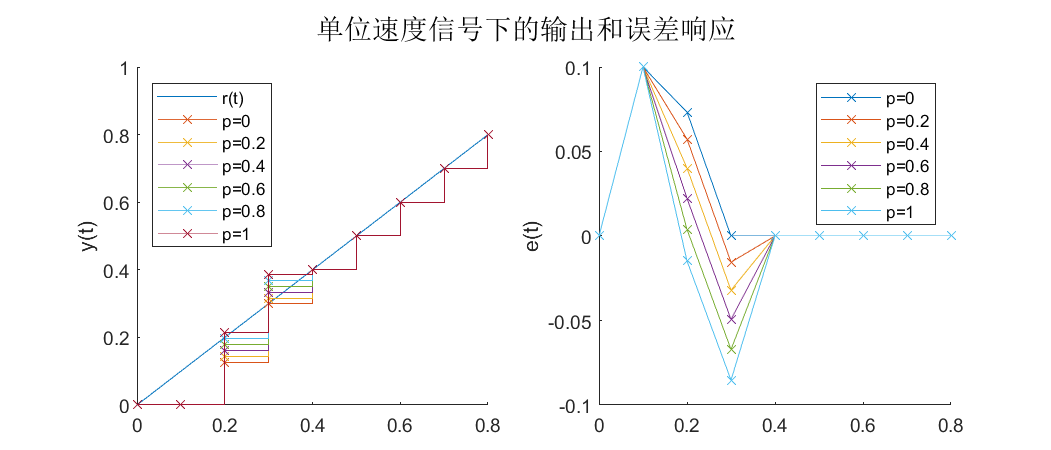

figure('Position',[0,0,700,300]);
t=0:0.1:0.8;
r=t';%单位速度信号
subplot(1,2,1);hold on
plot(t,r);
subplot(1,2,2);hold on
for i=1:N
    y=lsim(WB3(i),r,t);
    subplot(1,2,1)
    stairs(t,y,'x-');
    subplot(1,2,2)
    plot(t,r-y,'x-');
end
subplot(1,2,1)
legend(labels,'Location',"northwest");
ylabel('y(t)');
subplot(1,2,2);
ylabel('e(t)');
sgtitle('单位速度信号下的输出和误差响应');
legend(labels{2:end})
hold off;

当输入信号为单位阶跃信号时

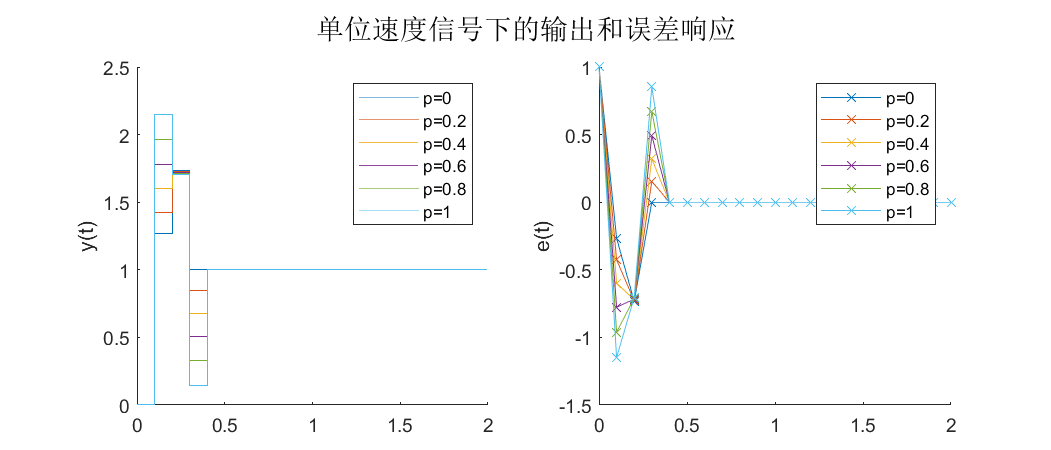

figure('Position',[0,0,700,300]);
subplot(1,2,1);hold on
subplot(1,2,2);hold on
for i=1:N
    [y,t]=step(WB3(i));
    subplot(1,2,1)
    stairs(t,y,'-');
    subplot(1,2,2);
    plot(t,1.-y,'x-');
end
subplot(1,2,1)
legend(labels{2:end},'Location',"northeast");
ylabel('y(t)');
subplot(1,2,2);
ylabel('e(t)');
sgtitle('单位速度信号下的输出和误差响应');
legend(labels{2:end})
hold off;

当输入信号为单位加速度信号时

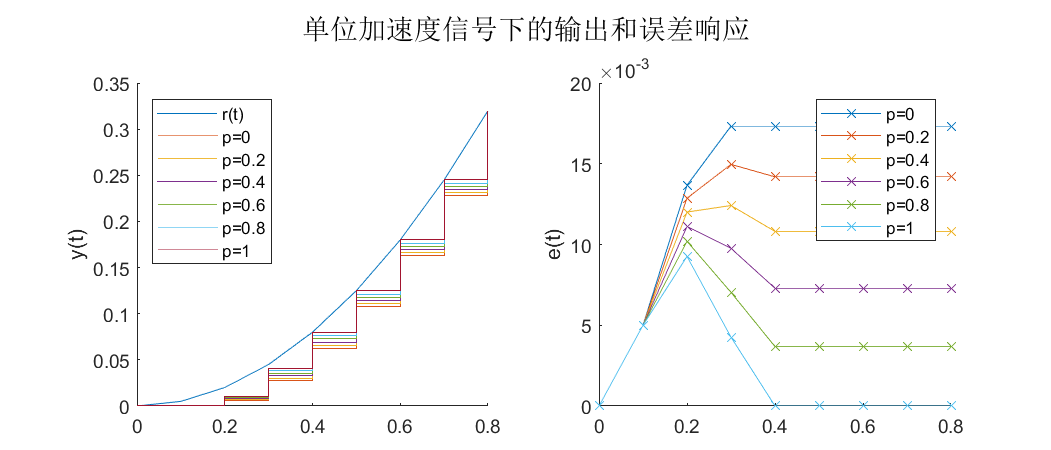

figure('Position',[0,0,700,300]);
t=(0:0.1:0.8)';
r=1/2*t.*t;%单位加速度信号
subplot(1,2,1);hold on
plot(t,r);
subplot(1,2,2);hold on
for i=1:N
    y=lsim(WB3(i),r,t);
    subplot(1,2,1)
    stairs(t,y,'-');
    subplot(1,2,2)
    plot(t,r-y,'x-');
end
subplot(1,2,1)
legend(labels,'Location',"northwest");
subplot(1,2,1)
legend(labels,'Location',"northwest");
ylabel('y(t)');
subplot(1,2,2);
ylabel('e(t)');
sgtitle('单位加速度信号下的输出和误差响应');
legend(labels{2:end})
hold off;